## `Review and analysis of CO2 photoreduction kinetics`

#### `Warren A. Thompson, Eva S. Fernandez and M. Mercedes Maroto-Valer`

`Research Centre for Carbon Solutions (RCCS), School of Engineering & Physical Sciences, Heriot-Watt University, Edinburgh, EH14 4AS`

## Supplementary information S1-AlgIt 

## A walk through comparison of multi-start trust-region,

## genetic algorithm and particle swarm methods for 

## estimating nonlinear CO2 photoreduction

## kinetic model coefficients

Number of pages = 13

Number of figures = 7

See excellent MATLAB documentation for more information for the trust-region method

[https://uk.mathworks.com/help/optim/ug/constrained-nonlinear-optimization-algorithms.html](https://uk.mathworks.com/help/optim/ug/constrained-nonlinear-optimization-algorithms.html)

MATLAB R2018b used

### Data reported by Tan 

L.-L. Tan, W.-J. Ong, S.-P. Chai and A. R. Mohamed, Chemical Engineering Journal, 2017, 308, 248–255

- Extracted CH4 data at different partial pressures of CO2 from Figure 3 (a) using [WebPlotDigitizer](https://automeris.io/WebPlotDigitizer)

- Extracted CH4 data at different partial pressures of H2O from Figure 3 (b) using [WebPlotDigitizer](https://automeris.io/WebPlotDigitizer)

### Copy and paste these settings to run the script below

(Partial pressure CO2 (bar), partial pressure H2O (bar), CH4 production (umol.gcat-1.h-1), I (mW/cm2), reported  model coefficients and constraints used for mean median model in order of: k, alpha, KH2O and KCO2 )

experimental_settings_PCO2 = [0 0.25 0.5 0.75 0.9 1.01];

experimental_settings_PH2O = 0.043;

reported_CH4_production = [0 0.172 0.202 0.212 0.385 0.336];

I = 81;

reported_coefficients = [84.42 4.4E-2 8.070 1.93E-2];

lower_constraint = [0 0 0 0];

upper_constraint = [100 0.5 30 0.5];

## Please enter data and experimental settings used to fit the model

% Copy and paste experimental settings, production data and reported coeffients
% as code - highlight text and click "Code" icon in "LIVE EDITOR" ribbon
experimental_settings_PCO2 = [0 0.25 0.5 0.75 0.9 1.01];
experimental_settings_PH2O = 0.043;
reported_CH4_production = [0 0.172 0.202 0.212 0.385 0.336];
I = 81;
reported_coefficients = [84.42 4.4E-2 8.070 1.93E-2];
lower_constraint = [0 0 0 0];
upper_constraint = [100 0.5 30 0.5];

pressure_settings = ones(numel(experimental_settings_PCO2),2);
pressure_settings(:,1) = pressure_settings(:,1).*experimental_settings_PCO2';
pressure_settings(:,2) = pressure_settings(:,2).*experimental_settings_PH2O;
                     

## Please enter values 

- For number of loops median multi-start trust -region method will run 

- Number of iterations per median loop

- Number of multi-start points 

% Set the number of times the iteration of the algorithm iterations method 
% will loop. Must be set to > 1 so that standard deviation and stats 
% comparison is possible

number_for_std_deviation_calculation = 10;   

% Set the number times the algorithm method will iterate
% within number of loops set above 
number_method_iterations = 50;            


## Line changes optional - Median multi-start (MS) 

## trust-region method

- This is the median MS trust-region method

- After each MS iteration, the median of the coefficients estimated will be saved in an array

- After each MS iteration, the values with the lowest error will be saved in an array

% Two site kinetic model
% b(1) = k, b(2) = alpha, b(3) = KH2O and b(4) = KCO2

Two_site_LH_model = @(b,pressure_settings)...
                     (b(1).*I.^b(2).*(b(3).*pressure_settings(:,2).*b(4).*...
                     pressure_settings(:,1)))./...
                     ((1 + (b(3).*pressure_settings(:,2))...
                     + (b(4).*pressure_settings(:,1))).^2);

% Set number of starting points for multi-start algorithm
no_multi_start_points = 10; 

% Assign empty data array to record the median value after each loop of
% multi-start trust-region iterations is complete
multiple_MS_median_approach_values = [];
multiple_MS_error_approach_values  = [];
all_MS_values = [];

% Assign empty data array to record the coefficient estimates for each 
% multi-start solution
MS_model_values        = [];
MS_model_values_errors = [];

for std_deviation_run = 1:number_for_std_deviation_calculation
     
    for median_run = 1:number_method_iterations
        
        % Randomly select intial starting point values between upper and 
        % lower constraint values
        Random_starting_point_values = (upper_constraint-lower_constraint)....
                                        *rand(1,1) + lower_constraint;

        problem = createOptimProblem('lsqcurvefit','x0',...
                                     Random_starting_point_values,'objective',...
                                     Two_site_LH_model,'lb',lower_constraint,...
                                     'ub',upper_constraint,'xdata',...
                                     pressure_settings,'ydata',...
                                     reported_CH4_production');

        ms = MultiStart('Display','off');
        [xMS,fvalMS] = run(ms,problem, no_multi_start_points);
        
        MS_model_values(median_run,1:numel(lower_constraint)) = xMS;
        MS_model_values_errors(median_run,1) = fvalMS;
               
    end
 
 % Lets collect the coefficient values based on median approach 
 % for each round   
 multiple_MS_median_approach_values(std_deviation_run,...
 1:numel(lower_constraint)) = median(MS_model_values);
 
 % Lets collect the coefficient values based on lowest error approach 
 % for each round 
 [M,I] = min(MS_model_values_errors);
 multiple_MS_error_approach_values(std_deviation_run,...
 1:numel(lower_constraint)) = MS_model_values(I,1:numel(lower_constraint));
 
 % Let's collect all of the multistart values for plotting histograms later
 all_MS_values = [all_MS_values;MS_model_values];
 
end


## Line changes optional - Median genetic algorithm (GA) 

## method

- This is the median GA method

- After each GA iteration, the median of the coefficients estimated will be saved in an array

- After each GA iteration, the values with the lowest error will be saved in an array

% Call GAmin function to assign sum of squares as objective function

fun_GA = @(b)minObj(b,pressure_settings,I,reported_CH4_production);

% Assign empty data array to record the GA values after each loop of
% multi-start trust-region iterations is complete
multiple_GA_median_approach_values = [];
multiple_GA_error_approach_values  = [];
all_GA_values               = [];


% Assign empty data array to record the coefficient estimates for each 
% GA solution
GA_model_values        = [];
GA_model_values_errors = [];


for std_deviation_run = 1:number_for_std_deviation_calculation
     
    for median_run = 1:number_method_iterations
        
        options = optimoptions('ga','Display','off');
        [xGA,fvalGA] = ga(fun_GA,4,[],[],[],[],lower_constraint,...
                          upper_constraint,[],options);
        
        GA_model_values(median_run,1:numel(lower_constraint)) = xGA;
        GA_model_values_errors(median_run,1) = fvalGA;
               
    end
 
 % Lets collect the coefficient values based on median GA approach 
 % for each round   
 multiple_GA_median_approach_values(std_deviation_run,...
 1:numel(lower_constraint)) = median(GA_model_values);
 
 % Lets collect the coefficient values based on lowest error 
 % GA approach for each round 
 
 [M,I] = min(GA_model_values_errors);
 multiple_GA_error_approach_values(std_deviation_run,...
 1:numel(lower_constraint)) = GA_model_values(I,1:numel(lower_constraint));
 
 % Let's collect all of the GA values for plotting histograms later
 all_GA_values = [all_GA_values;GA_model_values];
 
end

## Line changes optional - Median particle swarm (PS) 

## method

- This is the median PS method

- After each PS iteration, the median of the coefficients estimated will be saved in an array

- After each PS iteration, the values with the lowest error will be saved in an array

% Call PSmin function to assign sum of squares as objective function

fun_PS = @(b)minObj(b,pressure_settings,I,reported_CH4_production);

% Assign empty data array to record the GA values after each loop of
% multi-start trust-region iterations is complete
multiple_PS_median_approach_values = [];
multiple_PS_error_approach_values  = [];
all_PS_values               = [];


% Assign empty data array to record the coefficient estimates for each 
% GA solution
PS_model_values        = [];
PS_model_values_errors = [];


for std_deviation_run = 1:number_for_std_deviation_calculation
     
    for median_run = 1:number_method_iterations
        
        options = optimoptions('particleswarm','Display','off');
        [xPS,fvalPS] = particleswarm(fun_PS,4,lower_constraint,...
                                     upper_constraint,options);
        
        PS_model_values(median_run,1:numel(lower_constraint)) = xPS;
        PS_model_values_errors(median_run,1) = fvalPS;
               
    end
 
 % Lets collect the coefficient values based on median GA approach 
 % for each round   
 multiple_PS_median_approach_values(std_deviation_run,...
 1:numel(lower_constraint)) = median(PS_model_values);
 
 % Lets collect the coefficient values based on lowest error 
 % GA approach for each round 
 [M,I] = min(PS_model_values_errors);
 multiple_PS_error_approach_values(std_deviation_run,...
 1:numel(lower_constraint)) = PS_model_values(I,1:numel(lower_constraint));
 
 % Let's collect all of the GA values for plotting histograms later
 all_PS_values = [all_PS_values;PS_model_values];
 
end

## How do the different approaches compare?

- Lets compare the spread of coefficient values estimated using histograms

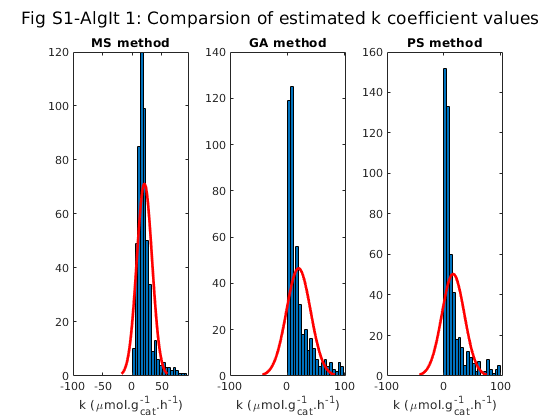

x_label = ["k (\mumol.g_{cat}^{-1}.h^{-1})" "\alpha" "K_{H_{2}O}" + ...
           "(bar^{-1})" "K_{CO_2} (bar^{-1})"];
       
% Set maximum histogram plot height, will need to increase for higher
% values set for: 'number_for_std_deviation_calculation' and/or 
% 'number_median_iterations'
max_height=200; 

figure;
% Plot histogram and median line for k coefficient estimates for different
% approaches
subplot(1,3,1); 
histfit(all_MS_values(:,1),20); xlabel(x_label(1), 'FontSize', 20);
title('MS method')
subplot(1,3,2); 
histfit(all_GA_values(:,1),20); xlabel(x_label(1), 'FontSize', 20);
title('GA method')
subplot(1,3,3); 
histfit(all_PS_values(:,1),20); xlabel(x_label(1), 'FontSize', 20);
title('PS method')
sgtitle('Fig S1-AlgIt 1: Comparsion of estimated k coefficient values')

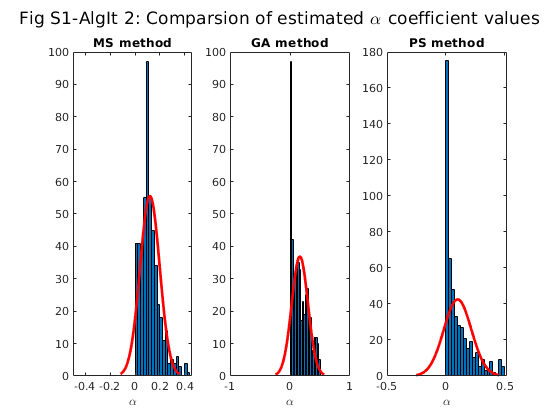

figure;
% Plot histogram and median line for alpha coefficient estimates for different
% approaches
subplot(1,3,1); 
histfit(all_MS_values(:,2),20); xlabel(x_label(2), 'FontSize', 20);
title('MS method')
subplot(1,3,2); 
histfit(all_GA_values(:,2),20); xlabel(x_label(2), 'FontSize', 20);
title('GA method')
subplot(1,3,3); 
histfit(all_PS_values(:,2),20); xlabel(x_label(2), 'FontSize', 20);
title('PS method')
sgtitle('Fig S1-AlgIt 2: Comparsion of estimated \alpha coefficient values')

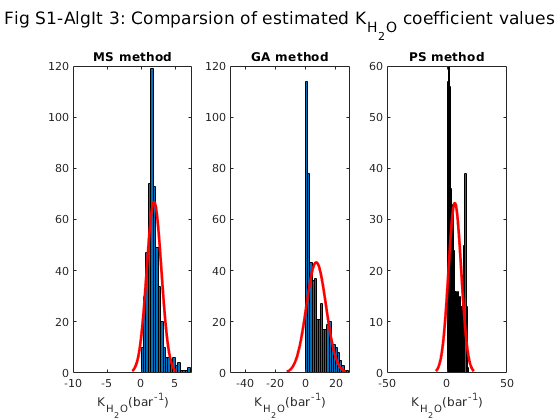

figure;
% Plot histogram and median line for KH2O coefficient estimates for different
% approaches
subplot(1,3,1); 
histfit(all_MS_values(:,3),20); xlabel(x_label(3), 'FontSize', 20);
title('MS method')
subplot(1,3,2); 
histfit(all_GA_values(:,3),20); xlabel(x_label(3), 'FontSize', 20);
title('GA method')
subplot(1,3,3); 
histfit(all_PS_values(:,3),20); xlabel(x_label(3), 'FontSize', 20);
title('PS method')
sgtitle('Fig S1-AlgIt 3: Comparsion of estimated K_{H_2O} coefficient values')

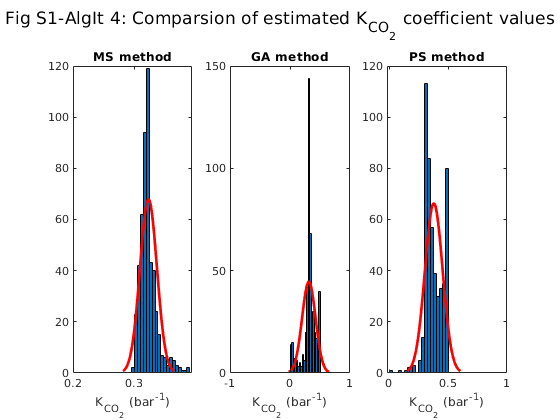

figure;
% Plot histogram and median line for KCO2 coefficient estimates for different
% approaches
subplot(1,3,1); 
histfit(all_MS_values(:,4),20); xlabel(x_label(4), 'FontSize', 20);
title('MS method')
subplot(1,3,2); 
histfit(all_GA_values(:,4),20); xlabel(x_label(4), 'FontSize', 20);
title('GA method')
subplot(1,3,3); 
histfit(all_PS_values(:,4),20); xlabel(x_label(4), 'FontSize', 20);
title('PS method')
sgtitle('Fig S1-AlgIt 4: Comparsion of estimated K_{CO_2} coefficient values')

## Does choosing the coeffients with the lowest error yield

## reproducible results? 

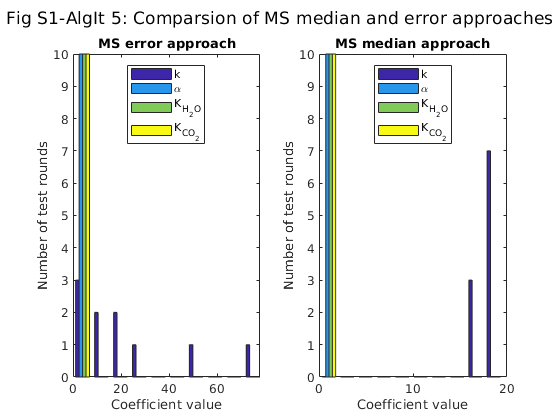

% Are the approaches repeatable?
figure;
subplot(1,2,1); 
hist(multiple_MS_error_approach_values);
title('MS error approach');
xlabel('Coefficient value');
ylabel('Number of test rounds'); 
legend({'k', '\alpha', 'K_{H_2O}', 'K_{CO_2}'},'Location','north');
subplot(1,2,2); 
hist(multiple_MS_median_approach_values);
title('MS median approach');
xlabel('Coefficient value');
ylabel('Number of test rounds'); 
legend({'k', '\alpha', 'K_{H_2O}', 'K_{CO_2}'},'Location','north');
sgtitle('Fig S1-AlgIt 5: Comparsion of MS median and error approaches')

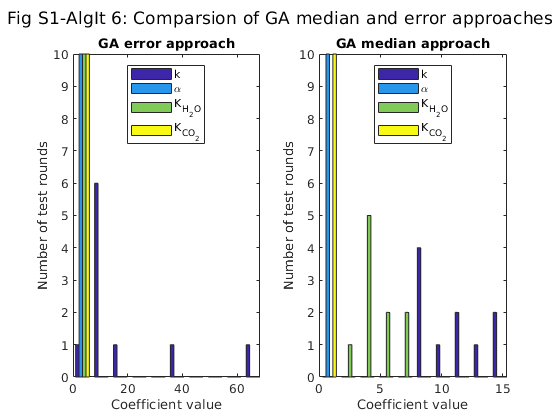


figure;
subplot(1,2,1); 
hist(multiple_GA_error_approach_values);
title('GA error approach');
xlabel('Coefficient value');
ylabel('Number of test rounds'); 
legend({'k', '\alpha', 'K_{H_2O}', 'K_{CO_2}'},'Location','north');
subplot(1,2,2); 
hist(multiple_GA_median_approach_values);
title('GA median approach');
xlabel('Coefficient value');
ylabel('Number of test rounds'); 
legend({'k', '\alpha', 'K_{H_2O}', 'K_{CO_2}'},'Location','north');
sgtitle('Fig S1-AlgIt 6: Comparsion of GA median and error approaches')

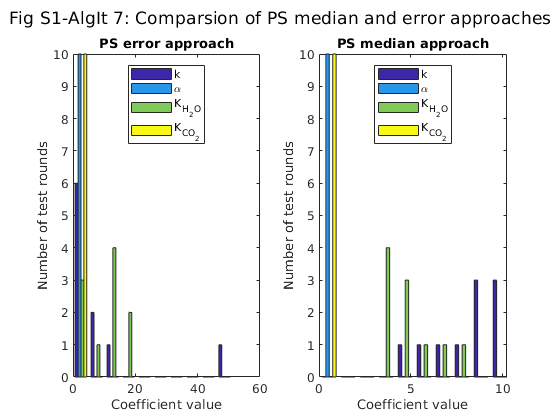


figure;
subplot(1,2,1); 
hist(multiple_PS_error_approach_values);
title('PS error approach');
xlabel('Coefficient value');
ylabel('Number of test rounds'); 
legend({'k', '\alpha', 'K_{H_2O}', 'K_{CO_2}'},'Location','north');
subplot(1,2,2); 
hist(multiple_PS_median_approach_values);
title('PS median approach');
xlabel('Coefficient value');
ylabel('Number of test rounds'); 
legend({'k', '\alpha', 'K_{H_2O}', 'K_{CO_2}'},'Location','north');
sgtitle('Fig S1-AlgIt 7: Comparsion of PS median and error approaches')

## Sum of squares objective function

function sse = minObj(b,pressure_settings,irradiance,production_data)

I = irradiance;
y = production_data';

sse =  sum(((b(1).*I.^b(2).*(b(3).*pressure_settings(:,2).*b(4).*...
        pressure_settings(:,1)))./((1 + (b(3).*pressure_settings(:,2))...
        + (b(4).*pressure_settings(:,1))).^2) - y).^2);
end